# DatasetConstruction

This script demonstrates how to detect ripple events in the local field potential data and how the detected events can be inspected and modified using the LFPViewer

May 2022, Linus Meienberg

## Import Dependencies

addpath(genpath('C:\Users\Linus Meienberg\Documents\MultiAreaBundleProject\RippleAnalysis')) % NT Group Multi Area Bundle Project Github Repo
addpath(genpath('C:\\Users\\Linus Meienberg\\Documents\\Buzcode')); % Buszaki Lab Buzcode Github Repo

## Import downsampled electrophysiological recording

For analysis of local field potential events, the high frequency content of the electrophysiological recordings can be ignored. We work with a downsampled recording file which has a samplerate of 2kHz. 

From the recording file we import a subset of channels at the ventral end of the second shank which is implanted in the dorsal hippocamus. Note that the ennumeration of channels in matlab is shifted by one with respect to the channel numbers in the channel map file. Manual inspection of the recoding file shows that ripple events are mainly occuring on these channels.

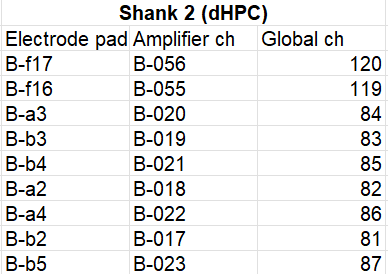

dHPC_ripple_channels = [120,85,84,86,83,87,82,88];
lfp = ImporterDAT_multi('D:\INI\SemesterArbeitBaran\rTBY33\7_freely_behav_220315_145519\amplifier_ds.dat',256,dHPC_ripple_channels);

## Filter traces

Design a digital band-pass filter for the frequency range from 130Hz to 245Hz to isolate ripple events.

d=designfilt('bandpassfir','FilterOrder',600,'StopbandFrequency1',125,'PassbandFrequency1',130,'PassbandFrequency2',245,'StopbandFrequency2',250,'SampleRate',2000);
lfp_detrended = detrend(double(lfp'));
lfp_filtered = filtfilt(d,lfp_detrended);

## Generate automatic ripple annotations

The Buzcode Repo contains a tool for detection of hippocampal ripples.

It allows to set the passband which is used for ripple detection. Here we use the bz_FindRipples script with two passband settings, once with a passband of 180Hz to 220Hz to favor detection of high frequency ripples. And once using a broader 120Hz to 220Hz passband to capture as many ripple events as possible.

For detection of the ripple events we can use a single channel in the recording file. Here we supply the first of the imported channels ( channel index 120) which corresponds to the second most ventral electrode pad of the dorsal hippocampus shank.

lfp_timestamps = (1:size(lfp_filtered,1))/2000;
[ripples_auto_hi] = bz_FindRipples(lfp_detrended(:,1),lfp_timestamps, 'durations',[20 100],'minDuration',5,'frequency',2000,'passband',[180 220],'EMGThresh',0); %Buzsaki uses 20ms for min duration

After detection by thresholding: 27573 events.
After ripple merge: 9430 events.
After peak thresholding: 2116 events.
After duration test: 2057 events.


[ripples_auto_low] = bz_FindRipples(lfp_detrended(:,1),lfp_timestamps, 'durations',[20 100],'minDuration',5,'frequency',2000,'passband',[120 220],'EMGThresh',0);

After detection by thresholding: 16966 events.
After ripple merge: 9389 events.
After peak thresholding: 2527 events.
After duration test: 2476 events.


## Detect Ripples from bandpass power signal

Experience shows that ripple detection with the bz_FindRipples script is imperfect. Some ripples are not labeled while some labeled intervals do not contain a ripple.

Since we will be able to sort out false positives using the ripple curation tool built in this project, it might be favourable to include more lfp events

The following code calculates the amplitude of the bandpass filtered lfp signal. Then we look for peaks in the signal amplitude that exceed an empirical threshold value.

We can further narrow down the ripple candidates by filtering for power peaks that have a certain minimal width (temporal extent) and are sufficiently far from other peaks.

lfp_filtered_hilbert = abs(hilbert(lfp_filtered));
lfp_filtered_hilbert_mean = mean(lfp_filtered_hilbert,2);
% histogram(lfp_filtered_hilbert_mean,100) % inspect bandpass power levels
detection_meanPowerPeakThreshold = 40;
detection_minPeakSeparationFrames = 0.01 * 2000;
detection_minPeakWidth = 0.010 * 2000; % minimum peak width / event duration
[meanPowerPeaksAmplitude, meanPowerPeaksLocation, meanPowerPeakWidth, ~] = findpeaks(lfp_filtered_hilbert_mean,'MinPeakDistance',...
    detection_minPeakSeparationFrames,'MinPeakHeight',detection_meanPowerPeakThreshold,...
    'MinPeakWidth',detection_minPeakWidth);
% calculate candidate intervals using the detected peak widths
n_candidates = numel(meanPowerPeaksAmplitude);
duration = min(meanPowerPeakWidth,150); % restrict half width to 300 frames (150ms@2kHz) max
candidate_intervals = [ meanPowerPeaksLocation - duration, meanPowerPeaksLocation + duration ] / 2000;
% merge overlapping and close events
detection_eventMergeTolerance = 0.01; % merge events that begin up to tolerance ms after prior event ended

merge_candidates = candidate_intervals(2:end,1) - candidate_intervals(1:end-1,2) < detection_eventMergeTolerance;

ripples_peakPower = [];
current_interval = candidate_intervals(1,:);
for i = 2:n_candidates
    if merge_candidates(i-1)
        current_interval = [current_interval(1) candidate_intervals(i,2)];
    else
        ripples_peakPower = [ripples_peakPower ; current_interval];
        current_interval = candidate_intervals(i,:);
    end
end
ripples_peakPower = [ripples_peakPower ; current_interval];

## Delete intersecting events with priority ripples_auto_hi > ripples_auto_low > ripples_peakPower

Optionally, we can get rid of overlapping events that have been detected using the different detection methods.

There is no functional requirement to do this but it prevents clutering with many overlapping event regions where ripples occur.

A simple solution is to get rid of any intervals that overlap an interval with higher precedence.

for i = 1:size(ripples_auto_hi.timestamps,1)
    interval = ripples_auto_hi.timestamps(i,:);
    % look for overlap to ripples_auto_low
    % intervals without intersection end before the reference intervals
    % start or start after the reference interval ends
    to_delete = ~(ripples_auto_low.timestamps(:,2) < interval(1) | interval(2) < ripples_auto_low.timestamps(:,1));
    ripples_auto_low.peakNormedPower(to_delete) = [];
    ripples_auto_low.peaks(to_delete) = [];
    ripples_auto_low.timestamps(to_delete,:) = [];
    % look for overlap to ripples_peak_power
    to_delete = ~(ripples_peakPower(:,2) < interval(1) | interval(2) < ripples_peakPower(:,1));
    ripples_peakPower(to_delete,:) = [];
end

% Delete intervals that intersect with ripples_auto_low
for i = 1:size(ripples_auto_low.timestamps,1)
    interval = ripples_auto_low.timestamps(i,:);
    % look for overlap to ripples_peak_power
    to_delete = ~(ripples_peakPower(:,2) < interval(1) | interval(2) < ripples_peakPower(:,1));
    ripples_peakPower(to_delete,:) = [];
end

## Assemble detected Ripples to dataset

We can gather the results from the different detection steps and concatenate them to a single list of detection intervals.

The information about which method was used to detect the ripple episodes can be stored in the ripple class assignment.

This way we can also investigate quantitative differences in the detection results.

n_ripples_tot = size(ripples_auto_hi.timestamps,1) + size(ripples_auto_low.timestamps,1) + size(ripples_peakPower,1);
ripple_timestamps = [ripples_auto_hi.timestamps ; ripples_auto_low.timestamps; ripples_peakPower];
ripple_classes = [zeros(size(ripples_auto_hi.timestamps,1),1) ; ones(size(ripples_auto_low.timestamps,1),1) ; 2*ones(size(ripples_peakPower,1),1) ];
ripple_classes = categorical(ripple_classes,[0 1 2],{'bzHigh','bzLow','pp'});

## Invoke LFPViewer on generated annotations

We can use LFPViewer to visualize the resulting dataset and investigate the differences between the different detection methods.

Additionally, we can label some of the detected intervalls as true ripple events manually or add some false positives. This can be useful in later steps of the ripple curation workflow.

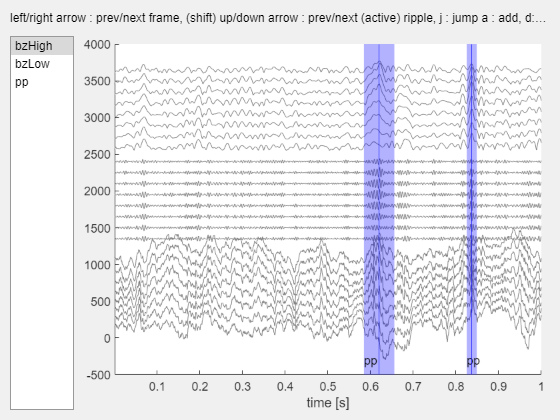

centers = sum(ripple_timestamps,2)/2;
viewer = LFPViewer([lfp_detrended lfp_filtered lfp_filtered_hilbert*4],2000,ripple_timestamps,centers,ripple_classes,false);